# Creating a Model 

## Author(s): Thomas Pfau, University of Luxembourg

## Reviewer(s):

## INTRODUCTION

This tutorial explains the most basic functions provided by The COBRA Toolbox  to create a model from scratch (i.e. define all relevant reactions and build a model from them). 

## MATERIALS

In this tutorial, two models are created: a small toy model and a simple model of glycolysis. The latter is also used in the model manipulation tutorial.

## PROCEDURE

**1. Create a simple toy model**

To create a new model, there is a simple function `createModel`:

emptymodel = createModel()

emptymodel =           rxns: {0×1 cell}
             S: []
            lb: [0×1 double]
            ub: [0×1 double]
             c: [0×1 double]
          mets: {0×1 cell}
             b: [0×1 double]
         rules: {0×1 cell}
         genes: {0×1 cell}
        osense: -1
        csense: ''
    rxnGeneMat: []


Calling it as above, yields an empty model `struct` with all required fields defined. To add reactions or metabolites please have a look at the tutorial for model manipulation.

There is also a possibility to immediately create a model with multiple reactions using `createModel`. To do so, a list of reaction identifiers, reaction names and reaction formulas has to be supplied.

Let's consider the following toy model:

The reactions are:

R1 = '1 Met1 + Met2 -> Met3'

R1 = 1 Met1 + Met2 -> Met3

R2 = 'Met3 <=> 2 Met4'

R2 = Met3 <=> 2 Met4

Reaction formulas are given as metabolites and their stoichiometric coefficient concatenated by +. Products and substrates are separated by a reversibility indicator, with `->` indicating an irreversible reaction and `<=>` indicating a reversible reaction.

To be able to use `createModel` to build this model, we also have to define the reaction Identifiers and the reaction names:

reactionIdentifiers = {'R1', 'R2'}

reactionIdentifiers =     'R1'    'R2'


reactionNames = {'Reaction 1', 'Reaction 2'}

reactionNames =     'Reaction 1'    'Reaction 2'


And we have to combine the reactions:

reactionFormulas = {R1, R2}

reactionFormulas =     '1 Met1 + Met2 -> Met3'    'Met3 <=> 2 Met4'


now we can call

model1 = createModel(reactionIdentifiers, reactionNames, reactionFormulas);

R1	Met1[c] + Met2[c] 	<=>	Met3[c] 


R2	Met3[c] 	<=>	2 Met4[c] 


to create the model including the two reactions. 

**2. Explanation of options for the createModel function**

`createModel` offers a couple of additional optional parameters. Those include:

- `revFlagList` - a double array of indications whether the reaction is reversible or not this will overwrite the indicator from the formula. (default: 1 for reversible formulas, 0 for irreversible formulas)

- `lowerBoundList` - a double array indicating the lower bounds of the providing reactions (again, this will overwrite both `revFlagList` and the indication from the formula). E.g. if a `revFlagList` entry indicates a reversible reaction, but the lower bound is >0, the reaction will be considered as irreversible. (The default is to assume 0 for irreversible and 1000 for reversible reactions)

- `upperBoundList` - a double array indicating the upper bounds of the reactions. (default: 1000)

- `subSystemList` - a cell array indicating the subSystems of the reactions

- `grRuleList` - a cell array indicating the GPR rules for a formula (in textual format e.g. Gene1 and Gene2)

- `geneNameList` - a List of genes present in the `grRuleList` array

- `systNameList` - a List (of equal size as `geneNameList`), that is used to translate the genes from those used in the `geneNameList` to those used in this list. 

**3. Creating a model with Gene-Protein-Reaction Association (GPR) rules**

Let's assume, our network has the following GPR associations:

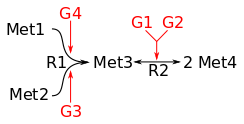

i.e. a complex of G1 and G2 catalyses R2 and either G3 or G4 catalyse R1. We further assume, that the flux maximum through R1 is 10 and 30 through R2

upperBounds = [10, 30];
grRuleR1 = 'G3 or G4';
grRuleR2 = 'G1 and G2';
grRuleList = {grRuleR1, grRuleR2};

The model creation call would then be:

model2 = createModel(reactionIdentifiers, reactionNames, reactionFormulas, ...
                     'upperBoundList', upperBounds, 'grRuleList', grRuleList);

New gene G3 added to model
New gene G4 added to model
R1	Met1[c] + Met2[c] 	<=>	Met3[c] 


New gene G1 added to model
New gene G2 added to model
R2	Met3[c] 	<=>	2 Met4[c] 


If we now compare the reactions, printing the GPR rules in both models

printRxnFormula(model1, 'gprFlag', 1);

R1	Met1[c] + Met2[c] 	<=>	Met3[c] 	
R2	Met3[c] 	<=>	2 Met4[c] 	


printRxnFormula(model2, 'gprFlag', 1);

R1	Met1[c] + Met2[c] 	<=>	Met3[c] 	G3 or G4
R2	Met3[c] 	<=>	2 Met4[c] 	G1 and G2


we see, that `model2` has assigned GPR rules, while `model1` does not have those.

**4. Create a model of the upper part of glycolysis**

We will now create a slightly more complex model (essentially, the upper part of the glycolysis) which will be used in other tutorials (e.g. ModelManipulation)

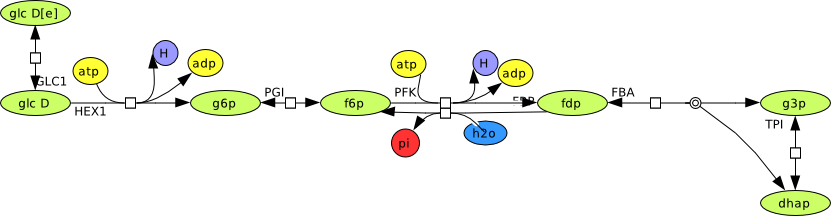

To create this model, we have to define the reactions:

reactionFormulas = {'glc-D[e]  -> glc-D',...
    'glc-D + atp  -> H + adp + g6p',...
    'g6p  <=> f6p',...
    'atp + f6p  -> H + adp + fdp',...
    'fdp + h2o  -> f6p + pi',...
    'fdp  -> g3p + dhap',...
    'dhap  -> g3p'};
reactionNames = {'GLCt1', 'HEX1', 'PGI', 'PFK', 'FBP', 'FBA', 'TPI'};
lowerBounds = [-20, 0, -20, 0, 0, -20, -20];
upperBounds = [20, 20, 20, 20, 20, 20, 20];
glycolysisModel = createModel(reactionNames, reactionNames, reactionFormulas,...
                             'lowerBoundList', lowerBounds, 'upperBoundList', upperBounds);

GLCt1	glc-D[e] 	<=>	glc-D[c] 


HEX1	glc-D[c] + atp[c] 	->	H[c] + adp[c] + g6p[c] 


PGI	g6p[c] 	<=>	f6p[c] 


PFK	atp[c] + f6p[c] 	->	H[c] + adp[c] + fdp[c] 


FBP	fdp[c] + h2o[c] 	->	f6p[c] + pi[c] 


FBA	fdp[c] 	<=>	g3p[c] + dhap[c] 
TPI	dhap[c] 	<=>	g3p[c] 
